N_a = 3

N_a = 3

r0 = randn(3,N_a);
% r0 = r0 - mean(r0,2);
w = randn(3,1);
y = randn(3*N_a, 1);

f = @(vec_r) dAdr(y,reshape(vec_r,3,[]),w);

jac_f = numeric_jacobian(f, r0(:));

[~, F] = dAdr(y,r0,w);


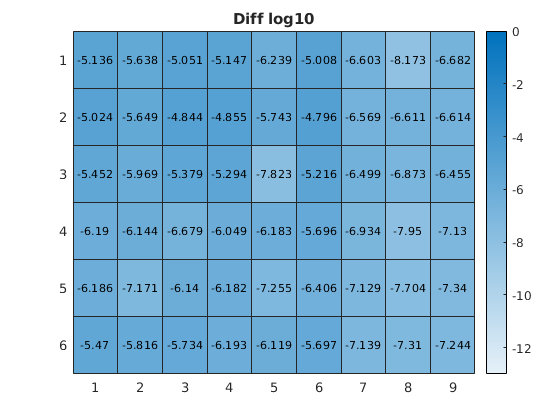

figure; 
heatmap(log10(abs(F-jac_f)), 'ColorLimits',[-13 0])
title("Diff log10")

% set(gca, 'clim', [-13 0]);

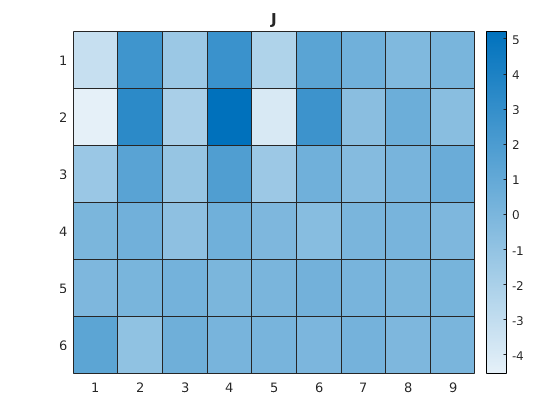

figure()
heatmap(F)
title("J")

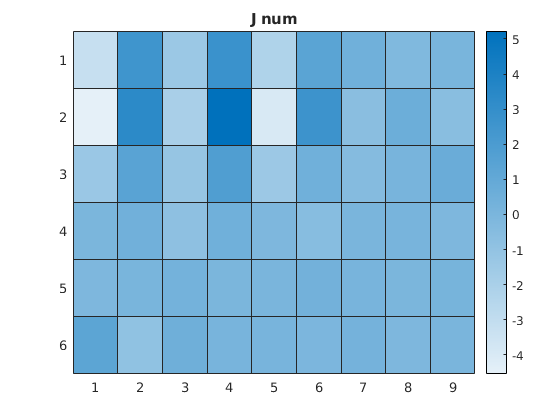

figure()
heatmap(jac_f)
title("J num")

% set(gca,'ColorScale','log')
% set(gca,
norm(F-jac_f)

ans = 3.3789e-05